# 多値出力モデルの例(サッカーの場合)

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む

load sample_multiOut.mat

ある日付以降のMasseyレーティングとホームアドバンテージを算出済み．

両チームそれぞれから見たレーティング差と勝点を算出

rateDiff=MasseyRatings_HA(:,1)-MasseyRatings_HA(:,2);
rateDiff=[rateDiff;-rateDiff];  %両方のチームから見たレーティング差に拡張
ActualWDL=[ActualWDL;fliplr(ActualWDL)];
ActualPoint=ActualWDL*[3;1;0];  %両方のチームから見た勝点に拡張
[min(rateDiff) max(rateDiff)]   %レーティング差の範囲

ans =    -3.0303    3.0303


試合結果(勝点)の種類

pointTypes=unique(ActualPoint)

pointTypes =      0
     1
     3


勝点の値ごとにそれ以下となる確率をロジスティック回帰で求める

for n1=1:size(pointTypes,1)
    mdl(n1,:)=glmfit(rateDiff, ActualPoint<=pointTypes(n1),'binomial','link','logit');
end

mdl

mdl =    -0.5226   -0.3942
    0.5226   -0.3942
  102.5661   -0.0000


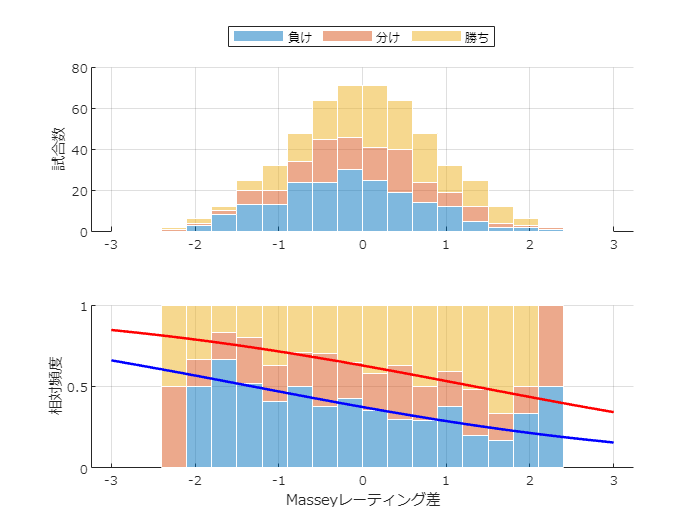

figure
hold on;
tiledlayout(2,1);
nexttile;set(gca,'fontname','メイリオ');grid on;hold on;
bins=(-1:0.1:1)*3;
hCounts=[]; %各階級の度数
for n1=1:size(pointTypes,1)
    ind(:,n1)= ActualPoint==pointTypes(n1);
end
for n1=1:size(pointTypes,1)
    hCounts(:,n1)=histcounts(rateDiff(ind(:,n1)),bins);
end

bObj=bar(movmean(bins,2,'Endpoints','discard'), hCounts,'stacked', ...
    'EdgeColor','w','BarWidth',1);
ylabel('試合数');
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');

nexttile;set(gca,'fontname','メイリオ');grid on;hold on;
bObj=bar(movmean(bins,2,'Endpoints','discard'), ...
    hCounts./sum(hCounts,2),'stacked', ...
    'EdgeColor','w','BarWidth',1);
bObj(1).FaceAlpha=0.5;
bObj(2).FaceAlpha=0.5;
bObj(3).FaceAlpha=0.5;
xlabel('Masseyレーティング差');
ylabel('相対頻度');
plot(bins, glmval(mdl(1,:)',bins,"logit"),'b-','LineWidth',1.5);
plot(bins, glmval(mdl(2,:)',bins,"logit"),'r-','LineWidth',1.5);
exportgraphics(gcf,'fig_JLeague_multiOutHist.pdf');

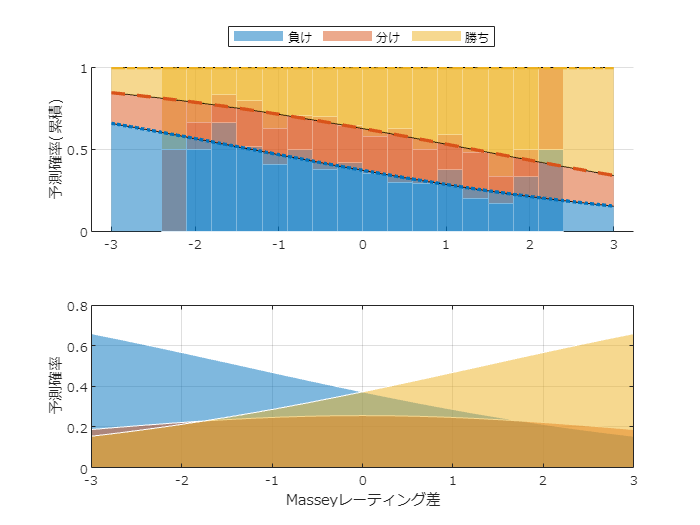

figure
tiledlayout(2,1)
nexttile;
hold on;
bar(movmean(bins,2,'Endpoints','discard'), ...
    hCounts./sum(hCounts,2),'stacked', ...
    'EdgeColor','w','BarWidth',1,'FaceAlpha',0.5);

lineStyleStr={':','--','-.','-'};
areaData=[];
for n1=1:size(pointTypes,1)
    if n1==1
        plotY=glmval(mdl(n1,:)',bins,"logit");
    else
        plotY=glmval(mdl(n1,:)',bins,"logit") ...
            -glmval(mdl(n1-1,:)',bins,"logit");
    end
    areaData=[areaData;plotY'];
end
set(gca,'colororderindex',1)
area(bins',areaData','FaceAlpha',0.5)
set(gca,'colororderindex',1)

for n1=1:size(pointTypes,1)
    h(n1)=plot(bins, glmval(mdl(n1,:)',bins,"logit"),'LineWidth',2, ...
        LineStyle=lineStyleStr{n1});
end
grid on;
set(gca,'fontname','メイリオ');
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');
ylabel('予測確率(累積)');

nexttile;
area(bins,glmval(mdl(1,:)',bins,"logit"),'FaceAlpha',0.5,'EdgeColor','w');
set(gca,'fontname','メイリオ');grid on;hold on;
area(bins,glmval(mdl(2,:)',bins, "logit")-  glmval(mdl(1,:)',bins,"logit"), ...
    'FaceAlpha',0.5,'EdgeColor','w');
area(bins,1-glmval(mdl(2,:)',bins, "logit"),'FaceAlpha',0.5,'EdgeColor','w');
xlabel('Masseyレーティング差');
ylabel('予測確率');
exportgraphics(gcf,'fig_JLeague_multiOutProb.pdf');